%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT

%Airfoil Parameters
Cla = 6

Cla = 6

Tmax = 0.12

Tmax = 0.1200

LocMaxT = 0.3

LocMaxT = 0.3000

PerLamFlow = 0.1

PerLamFlow = 0.1000


%Planform Parameters
b = 80; %ft
S = 1000; %ft^2
TaperRatio = 0.01:0.01:1;
Sexp = 900; %ft^2
SweepMaxT = 0; %Degrees
SweepQuartC = 0; %Degrees
Q = 1.01 %For HIGH or MID wing

Q = 1.0100

AR = 7

AR = 7


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
AirDens = DensRat*2.3769*10^-3; %Slug/ft^3
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


%Calc Lift Curve Slope
beta = sqrt(1-M^2)

beta = 0.8134

eta = Cla/(2*pi)

eta = 0.9549

CLa = (2*pi*AR*Sexp/S)/(2+sqrt(4+(AR^2*beta^2)/eta^2*(1+(tand(SweepMaxT)^2)/beta^2)))

CLa = 4.7756


%Induced Drag Factor
for x=1:100
    
    Ne = 0; %Num of engines ON TOP of Wing
    TaperFunc = 0.005*(1+1.5*(TaperRatio(x)-0.6)^2)
    K(x) = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/((cosd(SweepQuartC))^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)
    e(x) = 1/(pi*K(x)*AR)
end

TaperFunc = 0.0076

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e = 0.8204

TaperFunc = 0.0075

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208


TaperFunc = 0.0074

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213


TaperFunc = 0.0074

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217


TaperFunc = 0.0073

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221


TaperFunc = 0.0072

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225


TaperFunc = 0.0071

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229


TaperFunc = 0.0070

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233


TaperFunc = 0.0070

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237


TaperFunc = 0.0069

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241


TaperFunc = 0.0068

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245


TaperFunc = 0.0067

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249


TaperFunc = 0.0067

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252


TaperFunc = 0.0066

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256


TaperFunc = 0.0065

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259


TaperFunc = 0.0065

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263


TaperFunc = 0.0064

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266


TaperFunc = 0.0063

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269


TaperFunc = 0.0063

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272


TaperFunc = 0.0062

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276


TaperFunc = 0.0061

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279


TaperFunc = 0.0061

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282


TaperFunc = 0.0060

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284


TaperFunc = 0.0060

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287


TaperFunc = 0.0059

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e =     0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290


TaperFunc = 0.0059

K =     0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548    0.0548    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0547    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546    0.0546


e = 1×26
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293


TaperFunc = 0.0058

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×27
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295


TaperFunc = 0.0058

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×28
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298


TaperFunc = 0.0057

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×29
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300


TaperFunc = 0.0057

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0056

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0056

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0055

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0055

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0055

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0054

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0054

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0054

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0053

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0053

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0053

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0052

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0052

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0052

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0052

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0051

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0051

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0051

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0051

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0051

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0051

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0050

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0051

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0051

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0051

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0051

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0051

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0051

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0052

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0052

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0052

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0052

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0053

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0053

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0053

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0054

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0054

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0054

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0055

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0055

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0055

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0056

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0056

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0057

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0057

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0058

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0058

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0059

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0059

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0060

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0060

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0061

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0061

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


TaperFunc = 0.0062

K = 1×30
    0.0554    0.0554    0.0554    0.0553    0.0553    0.0553    0.0553    0.0552    0.0552    0.0552    0.0552    0.0551    0.0551    0.0551    0.0551    0.0550    0.0550    0.0550    0.0550    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0548    0.0548    0.0548    0.0548    0.0548


e = 1×30
    0.8204    0.8208    0.8213    0.8217    0.8221    0.8225    0.8229    0.8233    0.8237    0.8241    0.8245    0.8249    0.8252    0.8256    0.8259    0.8263    0.8266    0.8269    0.8272    0.8276    0.8279    0.8282    0.8284    0.8287    0.8290    0.8293    0.8295    0.8298    0.8300    0.8303


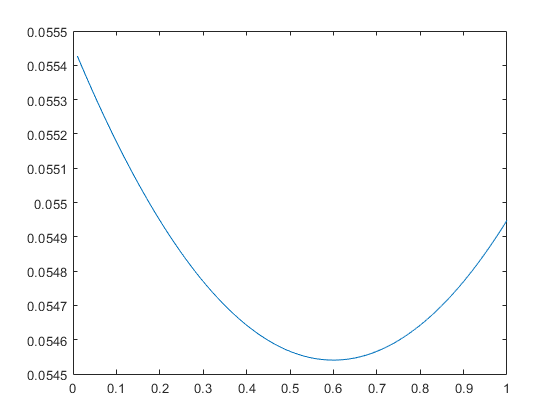


plot (TaperRatio,K)

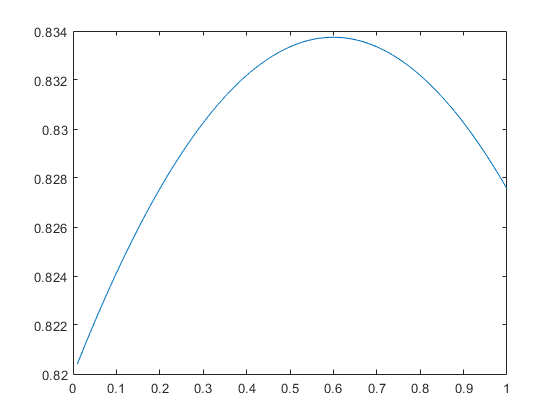

plot (TaperRatio,e)